close("all"); clear; clc;

A = [
    -1,-4;
    4,-1
    ];

b = 0.05;

ns = 100;
ts = 0.02;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

r = 0.2;
X0 = zonotope2d(r.*eye(2),[1.1;0.1] - r/2.*ones(2,1));

R = reachableSetGirard2005(X0,A,b,t);

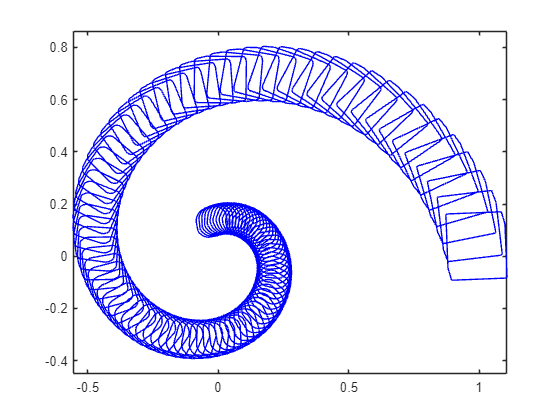

fig = figure();
axe = axes(fig);
% X0.plot();
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");